NUM_POINTS = 10000

NUM_POINTS = 10000

# Buck CCM

disp("Buck CCM")

Buck CCM


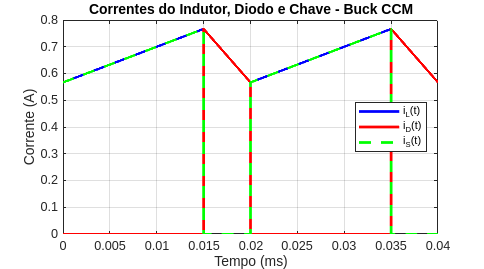


% Parametros de projeto
Vs = 200;
Vo = 150;
fs = 50 * 1e3;
P = 100;
delta_Vo = 0.1;
delta_Il = 0.3;
T = 1/fs;

% Calculo do duty cycle
D = Vo / Vs;

% Corrente no indutor (iL == iR)
R = (Vo^2)/P ;
iL = Vo/R;

% Corrente max e min no indutor
iL_min = iL - ((delta_Il * iL)/2);
iL_max = iL + ((delta_Il * iL)/2);

% Indutor
L = ((Vs - Vo) / (delta_Il * iL * fs) ) * D;

% Indutancia minima para CCM
Lmin = ((1 - D) * R * T) / 2;

% Capacitor
C = (Vo * (1 - D)) / (8 * L * delta_Vo * Vo * fs^2);

% Plotagem de 2 períodos
n_periodos = 2;
tempo_total = n_periodos * T;

% Resolução da simulação
pontos_por_periodo = NUM_POINTS;
tempo = linspace(0, tempo_total, n_periodos * pontos_por_periodo);

% Pré-alocar vetores
iL_sim = zeros(size(tempo));
iD_sim = zeros(size(tempo));
iS_sim = zeros(size(tempo)); % corrente da chave

% Gerar formas de onda para cada período
for k = 0:n_periodos-1
    
    idx_inicio = k * pontos_por_periodo + 1;
    idx_fim = (k+1) * pontos_por_periodo;
    
    t_periodo = tempo(idx_inicio:idx_fim) - k*T;
    
    % Corrente do indutor
    iL_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iL_periodo(n) = iL_min + (iL_max - iL_min) * (t_periodo(n)/(D*T));
        else
            iL_periodo(n) = iL_max - (iL_max - iL_min) * ((t_periodo(n)-D*T)/((1-D)*T));
        end
    end
    
    % Corrente do diodo
    iD_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iD_periodo(n) = 0;
        else
            iD_periodo(n) = iL_max - (iL_max - iL_min) * ((t_periodo(n)-D*T)/((1-D)*T));
        end
    end
    
    % Corrente da chave
    iS_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Igual à corrente do indutor
            iS_periodo(n) = iL_min + (iL_max - iL_min) * (t_periodo(n)/(D*T));
        else
            % Chave desligada
            iS_periodo(n) = 0;
        end
    end
    
    % Armazenar
    iL_sim(idx_inicio:idx_fim) = iL_periodo;
    iD_sim(idx_inicio:idx_fim) = iD_periodo;
    iS_sim(idx_inicio:idx_fim) = iS_periodo;
end

% Gráfico
figure('Position', [100, 100, 900, 500]);
plot(tempo * 1000, iL_sim, 'b-', 'LineWidth', 2);
hold on;
plot(tempo * 1000, iD_sim, 'r-', 'LineWidth', 2);
plot(tempo * 1000, iS_sim, 'g--', 'LineWidth', 2);
grid on;

xlabel('Tempo (ms)');
ylabel('Corrente (A)');
title('Correntes do Indutor, Diodo e Chave - Buck CCM');

legend('i_L(t)', 'i_D(t)', 'i_S(t)', 'Location', 'best');
xlim([0, tempo_total * 1000]);

hold off;


% Exibir valores calculados
fprintf('\n=== Valores Calculados ===\n');


=== Valores Calculados ===


fprintf('Tensão de entrada Vs = %.8f V\n', Vs);

Tensão de entrada Vs = 200.00000000 V


fprintf('Tensão de saída Vo = %.8f V\n', Vo);

Tensão de saída Vo = 150.00000000 V


fprintf('Tensão máxima na chave = %.8f V\n', Vs);

Tensão máxima na chave = 200.00000000 V


fprintf('Tensão máxima no diodo = %.8f V\n', Vs);

Tensão máxima no diodo = 200.00000000 V


fprintf('Duty cycle D = %.8f\n', D);

Duty cycle D = 0.75000000


fprintf('Resistência R = %.8f Ω\n', R);

Resistência R = 225.00000000 Ω


fprintf('Corrente média iL = %.8f A\n', iL);

Corrente média iL = 0.66666667 A


fprintf('iL_min = %.8f A\n', iL_min);

iL_min = 0.56666667 A


fprintf('iL_max = %.8f A\n', iL_max);

iL_max = 0.76666667 A


fprintf('Indutância L = %.8f mH\n', L*1000);

Indutância L = 3.75000000 mH


fprintf('Indutância mínima Lmin = %.8f mH\n', Lmin*1000);

Indutância mínima Lmin = 0.56250000 mH


fprintf('Capacitância C = %.8f μF\n', C*1e6);

Capacitância C = 0.03333333 μF



% Verificação da condição CCM
if L > Lmin
    fprintf('L (%.4f) > Lmin (%.4f): Opera em CCM ✓\n', L, Lmin);
else
    fprintf('Lmin (%.4f) < L (%.4f): Não opera em CCM\n', Lmin, L);
end

L (0.0037) > Lmin (0.0006): Opera em CCM ✓


# Buck DCM

disp("Buck DCM")

Buck DCM


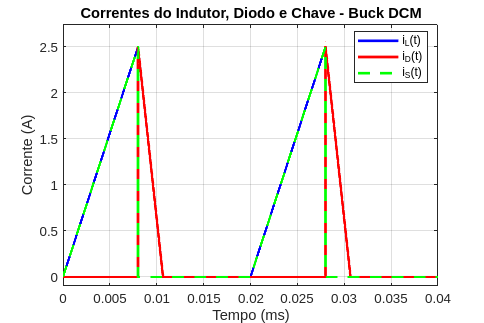


% Parametros de projeto
Vs = 200;
Vo = 150;
fs = 50 * 1e3;
P = 100;
delta_Vo = 0.1;
D = 0.4;
T = 1/fs;

% Indutor
R = (Vo^2)/P;
L = ((Vs - Vo) / (2 * (Vo^2)) ) * Vs * (D^2) * T * R;
iL_max = ((Vs - Vo)/L) * D * T;

% Capacitor
D1 = ((Vs * D) / Vo) - D;
D2 = 1 - D - D1;

C = (Vo * D2 * T) / (R * delta_Vo * Vo);

% D max / D critico
Dmax = 1 - ((2* L * fs)/R);

% Plotagem de 2 períodos
n_periodos = 2;
tempo_total = n_periodos * T;

% Resolução da simulação
pontos_por_periodo = NUM_POINTS;
tempo = linspace(0, tempo_total, n_periodos * pontos_por_periodo);

% Pré-alocar vetores
iL_sim = zeros(size(tempo));
iD_sim = zeros(size(tempo));
iS_sim = zeros(size(tempo));

% Gerar formas de onda para cada período
for k = 0:n_periodos-1
    idx_inicio = k * pontos_por_periodo + 1;
    idx_fim = (k+1) * pontos_por_periodo;
    
    t_periodo = tempo(idx_inicio:idx_fim) - k*T;
    
    % Corrente do indutor
    iL_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iL_periodo(n) = iL_max * (t_periodo(n)/(D*T));
        elseif t_periodo(n) <= (D + D1)*T
            t_rel = t_periodo(n) - D*T;
            iL_periodo(n) = iL_max * (1 - t_rel/(D1*T));
        else
            iL_periodo(n) = 0;
        end
    end
    
    % Corrente do diodo
    iD_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iD_periodo(n) = 0;
        elseif t_periodo(n) <= (D + D1)*T
            t_rel = t_periodo(n) - D*T;
            iD_periodo(n) = iL_max * (1 - t_rel/(D1*T));
        else
            iD_periodo(n) = 0;
        end
    end
    
    % Corrente da chave
    iS_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iS_periodo(n) = iL_periodo(n);
        else
            iS_periodo(n) = 0;
        end
    end
    
    % Armazenar
    iL_sim(idx_inicio:idx_fim) = iL_periodo;
    iD_sim(idx_inicio:idx_fim) = iD_periodo;
    iS_sim(idx_inicio:idx_fim) = iS_periodo;
end

% Gráfico
figure('Position', [100, 100, 900, 600]);
plot(tempo * 1000, iL_sim, 'b-', 'LineWidth', 2);
hold on;
plot(tempo * 1000, iD_sim, 'r-', 'LineWidth', 2);
plot(tempo * 1000, iS_sim, 'g--', 'LineWidth', 2);
grid on;
xlabel('Tempo (ms)');
ylabel('Corrente (A)');
title('Correntes do Indutor, Diodo e Chave - Buck DCM');
legend('i_L(t)', 'i_D(t)', 'i_S(t)', 'Location', 'best');
xlim([0, tempo_total * 1000]);
ylim([-0.1, iL_max * 1.1]);
hold off;


% Exibir valores calculados
fprintf('\n=== Valores Calculados para DCM ===\n');


=== Valores Calculados para DCM ===


fprintf('Tensão de entrada Vs = %.8f V\n', Vs);

Tensão de entrada Vs = 200.00000000 V


fprintf('Tensão de saída Vo = %.8f V\n', Vo);

Tensão de saída Vo = 150.00000000 V


fprintf('Tensão máxima na chave = %.8f V\n', Vs);

Tensão máxima na chave = 200.00000000 V


fprintf('Tensão máxima no diodo = %.8f V\n', Vs);

Tensão máxima no diodo = 200.00000000 V


fprintf('Resistência R = %.8f Ω\n', R);

Resistência R = 225.00000000 Ω


fprintf('Indutância L = %.8f mH\n', L*1000);

Indutância L = 0.16000000 mH


fprintf('iL_max = %.8f A\n', iL_max);

iL_max = 2.50000000 A


fprintf('D1 = %.8f\n', D1);

D1 = 0.13333333


fprintf('D2 = %.8f\n', D2);

D2 = 0.46666667


fprintf('Capacitância C = %.8f μF\n', C*1e6);

Capacitância C = 0.41481481 μF


fprintf('Dmax (D crítico) = %.8f\n', Dmax);

Dmax (D crítico) = 0.92888889



% Verificação da condição DCM
if Dmax > D
    fprintf('Dmax (%.4f) > D (%.4f): Opera em DCM ✓\n', Dmax, D);
else
    fprintf('Dmax (%.4f) < D (%.4f): Não opera em DCM\n', Dmax, D);
end

Dmax (0.9289) > D (0.4000): Opera em DCM ✓


# Buck-Boost CCM

disp("Buck-Boost CCM")

Buck-Boost CCM



% Parametros de projeto
Vs = 200;
Vo = 150;
fs = 50 * 1e3;
P = 100;
delta_Vo = 0.1;
delta_Il = 0.3;
T = 1/fs;

% Calculo do duty cycle
aux = (Vo/Vs);
D = aux / (1 + aux)

D = 0.4286


% Carga 
R = (Vo^2)/P 

R = 225


% Corrente média no indutor
iL = Vo / (R * (1 - D))

iL = 1.1667


% Corrente max e min no indutor
iL_min = iL - ((delta_Il * iL)/2)

iL_min = 0.9917

iL_max = iL + ((delta_Il * iL)/2)

iL_max = 1.3417


% Calculo do indutor
L = (Vs * D * T) / (delta_Il * iL)

L = 0.0049


% Calculo do capacitor
C = (Vo * D) / (delta_Vo * Vo * R * fs)

C = 3.8095e-07


% Indutancia minima para CCM
Lmin = (((1-D)^2)*R)/(2*fs)

Lmin = 7.3469e-04


if L > Lmin
    disp("L > Lmin: opera em CCM")
else
    disp("L < Lmin: nao opera em CCM")
end

L > Lmin: opera em CCM


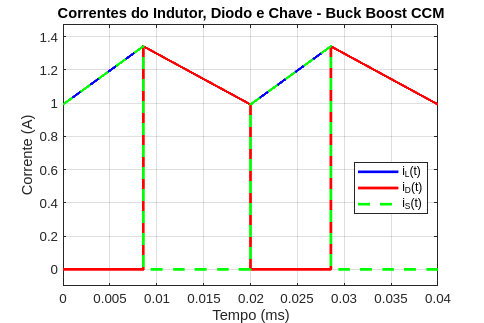


% Plotagem de 2 períodos
n_periodos = 2;
tempo_total = n_periodos * T;

% Resolução da simulação
pontos_por_periodo = NUM_POINTS;
tempo = linspace(0, tempo_total, n_periodos * pontos_por_periodo);

% Pré-alocar vetores
iL_sim = zeros(size(tempo));
iD_sim = zeros(size(tempo));
iS_sim = zeros(size(tempo));

% Gerar formas de onda para cada período
for k = 0:n_periodos-1
    % Índices para este período
    idx_inicio = k * pontos_por_periodo + 1;
    idx_fim = (k+1) * pontos_por_periodo;
    
    % Tempo dentro do período atual (0 a T)
    t_periodo = tempo(idx_inicio:idx_fim) - k*T;
    
    % Cálculo da corrente do indutor para este período (CCM)
    iL_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Instante 0 até DT: corrente vai de iL_min até iL_max
            iL_periodo(n) = iL_min + (iL_max - iL_min) * (t_periodo(n)/(D*T));
        else
            % Instante DT até T: corrente vai de iL_max até iL_min
            iL_periodo(n) = iL_max - (iL_max - iL_min) * ((t_periodo(n)-D*T)/((1-D)*T));
        end
    end
    
    % Cálculo da corrente do diodo para este período (Buck-Boost CCM)
    iD_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Instante 0 até DT: corrente do diodo fica em 0 (chave fechada)
            iD_periodo(n) = 0;
        else
            % Instante DT até T: corrente do diodo = corrente do indutor
            % (diodo conduz a corrente do indutor para a carga)
            if t_periodo(n) <= T
                iD_periodo(n) = iL_max - (iL_max - iL_min) * ((t_periodo(n)-D*T)/((1-D)*T));
            else
                iD_periodo(n) = 0;
            end
        end
    end

    % Corrente da chave
    iS_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iS_periodo(n) = iL_periodo(n);
        else
            iS_periodo(n) = 0;
        end
    end
    
    % Armazenar
    iL_sim(idx_inicio:idx_fim) = iL_periodo;
    iD_sim(idx_inicio:idx_fim) = iD_periodo;
    iS_sim(idx_inicio:idx_fim) = iS_periodo;
end

% Gráfico
figure('Position', [100, 100, 900, 600]);
plot(tempo * 1000, iL_sim, 'b-', 'LineWidth', 2);
hold on;
plot(tempo * 1000, iD_sim, 'r-', 'LineWidth', 2);
plot(tempo * 1000, iS_sim, 'g--', 'LineWidth', 2);
grid on;
xlabel('Tempo (ms)');
ylabel('Corrente (A)');
title('Correntes do Indutor, Diodo e Chave - Buck Boost CCM');
legend('i_L(t)', 'i_D(t)', 'i_S(t)', 'Location', 'best');
xlim([0, tempo_total * 1000]);
ylim([-0.1, iL_max * 1.1]);
hold off;


% Exibir valores calculados
fprintf('\n=== Valores Calculados para Buck-Boost CCM ===\n');


=== Valores Calculados para Buck-Boost CCM ===


fprintf('Tensão de entrada Vs = %.8f V\n', Vs);

Tensão de entrada Vs = 200.00000000 V


fprintf('Tensão de saída Vo = %.8f V\n', Vo);

Tensão de saída Vo = 150.00000000 V


fprintf('Tensão máxima na chave = %.8f V\n', Vs+Vo);

Tensão máxima na chave = 350.00000000 V


fprintf('Tensão máxima no diodo = %.8f V\n', Vs+Vo);

Tensão máxima no diodo = 350.00000000 V


fprintf('Duty cycle D = %.8f\n', D);

Duty cycle D = 0.42857143


fprintf('Resistência R = %.8f Ω\n', R);

Resistência R = 225.00000000 Ω


fprintf('Corrente média no indutor iL = %.8f A\n', iL);

Corrente média no indutor iL = 1.16666667 A


fprintf('iL_min = %.8f A\n', iL_min);

iL_min = 0.99166667 A


fprintf('iL_max = %.8f A\n', iL_max);

iL_max = 1.34166667 A


fprintf('Indutância L = %.8f mH\n', L*1000);

Indutância L = 4.89795918 mH


fprintf('Indutância mínima Lmin = %.8f mH\n', Lmin*1000);

Indutância mínima Lmin = 0.73469388 mH


fprintf('Capacitância C = %.8f μF\n', C*1e6);

Capacitância C = 0.38095238 μF



% Verificação da condição CCM
if L > Lmin
    fprintf('L (%.4f mH) > Lmin (%.4f mH): Opera em CCM ✓\n', L*1000, Lmin*1000);
else
    fprintf('L (%.4f mH) < Lmin (%.4f mH): Opera em DCM\n', L*1000, Lmin*1000);
end

L (4.8980 mH) > Lmin (0.7347 mH): Opera em CCM ✓



% Informação adicional sobre o conversor Buck-Boost
fprintf('\n=== Características do Conversor Buck-Boost ===\n');


=== Características do Conversor Buck-Boost ===


fprintf('Tensão de saída negativa: Vo = -%.2f V\n', Vo);

Tensão de saída negativa: Vo = -150.00 V


fprintf('Relação de conversão: Vo/Vs = %.4f\n', Vo/Vs);

Relação de conversão: Vo/Vs = 0.7500


# Buck-Boost DCM

disp("Buck-Boost DCM")

Buck-Boost DCM


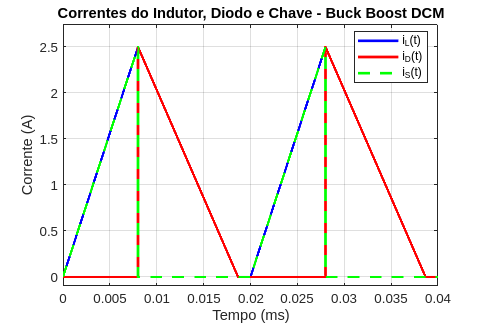


% Parametros de projeto
Vs = 200;
Vo = 150;
fs = 50 * 1e3;
P = 100;
delta_Vo = 0.1;
T = 1/fs;
D = 0.4;

% Carga 
R = (Vo^2)/P;

% Calculo de D1
aux = (Vo/Vs);
D1 = D / aux;
D2 = 1 - D1 - D;

% Indutor
L = (R * (D1^2)) / (2 * fs);
L = ((R * (D^2) * T)/2) * ((Vs/Vo)^2);
iL_max = (Vs * D * T)/L;

% Capacitor
C = (1/(R*delta_Vo)) * (1-D1) * T;

% D max / D critico
Dmax = 1 - sqrt((2* L * fs)/R);

% Plotagem de 2 períodos
n_periodos = 2;
tempo_total = n_periodos * T;

% Resolução da simulação
pontos_por_periodo = NUM_POINTS;
tempo = linspace(0, tempo_total, n_periodos * pontos_por_periodo);

% Pré-alocar vetores
iL_sim = zeros(size(tempo));
iD_sim = zeros(size(tempo));
iS_sim = zeros(size(tempo));

% Gerar formas de onda para cada período
for k = 0:n_periodos-1
    % Índices para este período
    idx_inicio = k * pontos_por_periodo + 1;
    idx_fim = (k+1) * pontos_por_periodo;
    
    % Tempo dentro do período atual (0 a T)
    t_periodo = tempo(idx_inicio:idx_fim) - k*T;
    
    % Cálculo da corrente do indutor para este período (Buck-Boost DCM)
    iL_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Instante 0 até D*T: corrente vai de 0 até iL_max (chave ligada)
            iL_periodo(n) = iL_max * (t_periodo(n)/(D*T));
        elseif t_periodo(n) <= (D + D1)*T
            % Instante D*T até (D+D1)*T: corrente vai de iL_max até 0 (diodo conduzindo)
            t_rel = t_periodo(n) - D*T;
            iL_periodo(n) = iL_max * (1 - t_rel/(D1*T));
        else
            % Instante (D+D1)*T até T: corrente fica em 0 (descontinuidade)
            iL_periodo(n) = 0;
        end
    end
    
    % Cálculo da corrente do diodo para este período (Buck-Boost DCM)
    iD_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Instante 0 até D*T: corrente do diodo fica em 0 (chave fechada)
            iD_periodo(n) = 0;
        elseif t_periodo(n) <= (D + D1)*T
            % Instante D*T até (D+D1)*T: corrente do diodo = corrente do indutor
            % (diodo conduz a corrente do indutor para a carga)
            t_rel = t_periodo(n) - D*T;
            iD_periodo(n) = iL_max * (1 - t_rel/(D1*T));
        else
            % Instante (D+D1)*T até T: corrente do diodo fica em 0
            iD_periodo(n) = 0;
        end
    end

    % Corrente da chave
    iS_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iS_periodo(n) = iL_periodo(n);
        else
            iS_periodo(n) = 0;
        end
    end
    
    % Armazenar
    iL_sim(idx_inicio:idx_fim) = iL_periodo;
    iD_sim(idx_inicio:idx_fim) = iD_periodo;
    iS_sim(idx_inicio:idx_fim) = iS_periodo;
end

% Gráfico
figure('Position', [100, 100, 900, 600]);
plot(tempo * 1000, iL_sim, 'b-', 'LineWidth', 2);
hold on;
plot(tempo * 1000, iD_sim, 'r-', 'LineWidth', 2);
plot(tempo * 1000, iS_sim, 'g--', 'LineWidth', 2);
grid on;
xlabel('Tempo (ms)');
ylabel('Corrente (A)');
title('Correntes do Indutor, Diodo e Chave - Buck Boost DCM');
legend('i_L(t)', 'i_D(t)', 'i_S(t)', 'Location', 'best');
xlim([0, tempo_total * 1000]);
ylim([-0.1, iL_max * 1.1]);
hold off;


% Exibir valores calculados
fprintf('\n=== Valores Calculados para Buck-Boost DCM ===\n');


=== Valores Calculados para Buck-Boost DCM ===


fprintf('Tensão de entrada Vs = %.8f V\n', Vs);

Tensão de entrada Vs = 200.00000000 V


fprintf('Tensão de saída Vo = %.8f V\n', Vo);

Tensão de saída Vo = 150.00000000 V


fprintf('Tensão máxima na chave = %.8f V\n', Vs+Vo);

Tensão máxima na chave = 350.00000000 V


fprintf('Tensão máxima no diodo = %.8f V\n', Vs+Vo);

Tensão máxima no diodo = 350.00000000 V


fprintf('Duty cycle D = %.8f\n', D);

Duty cycle D = 0.40000000


fprintf('Resistência R = %.8f Ω\n', R);

Resistência R = 225.00000000 Ω


fprintf('D1 = %.8f\n', D1);

D1 = 0.53333333


fprintf('D2 = %.8f\n', D2);

D2 = 0.06666667


fprintf('Indutância L = %.8f mH\n', L*1000);

Indutância L = 0.64000000 mH


fprintf('iL_max = %.8f A\n', iL_max);

iL_max = 2.50000000 A


fprintf('Capacitância C = %.8f μF\n', C*1e6);

Capacitância C = 0.41481481 μF


fprintf('Dmax (D crítico) = %.8f\n', Dmax);

Dmax (D crítico) = 0.46666667



% Verificação da condição DCM
if Dmax > D
    fprintf('Dmax (%.4f) > D (%.4f): Opera em DCM ✓\n', Dmax, D);
else
    fprintf('Dmax (%.4f) < D (%.4f): Não opera em DCM\n', Dmax, D);
end

Dmax (0.4667) > D (0.4000): Opera em DCM ✓



% Informações adicionais
fprintf('\n=== Características do Conversor Buck-Boost DCM ===\n');


=== Características do Conversor Buck-Boost DCM ===


fprintf('Tensão de saída negativa: Vo = -%.2f V\n', Vo);

Tensão de saída negativa: Vo = -150.00 V


fprintf('Relação de conversão: Vo/Vs = %.4f\n', Vo/Vs);

Relação de conversão: Vo/Vs = 0.7500


# Boost CCM

disp("Boost CCM")

Boost CCM



% Parametros de projeto
Vs = 200;
Vo = 260;
fs = 50 * 1e3;
P = 100;
delta_Vo = 0.1;
delta_Il = 0.3;
T = 1/fs;

% Carga 
R = (Vo^2)/P 

R = 676

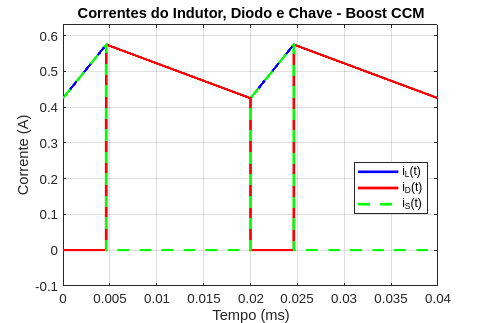


% Calculo do duty cycle
aux = Vo / Vs;
D = (aux - 1) / aux;
D = 1 - (Vs/Vo);

% Corrente média no indutor
iL = Vo / (R * (1 - D));

% Corrente max e min no indutor
iL_min = iL - ((delta_Il * iL)/2);
iL_max = iL + ((delta_Il * iL)/2);

% Indutor
L = (Vs * D) / (delta_Il * iL * fs);

% Capacitor
C = (Vo * D) / (delta_Vo * Vo * R * fs);

% Indutancia minima para CCM
Lmin = (D * ((1-D)^2) * R) / (2 * fs);

% Plotagem de 2 períodos
n_periodos = 2;
tempo_total = n_periodos * T;

% Resolução da simulação
pontos_por_periodo = NUM_POINTS;
tempo = linspace(0, tempo_total, n_periodos * pontos_por_periodo);

% Pré-alocar vetores
iL_sim = zeros(size(tempo));
iD_sim = zeros(size(tempo));
iS_sim = zeros(size(tempo));

% Gerar formas de onda para cada período
for k = 0:n_periodos-1
    % Índices para este período
    idx_inicio = k * pontos_por_periodo + 1;
    idx_fim = (k+1) * pontos_por_periodo;
    
    % Tempo dentro do período atual (0 a T)
    t_periodo = tempo(idx_inicio:idx_fim) - k*T;
    
    % Cálculo da corrente do indutor para este período (Boost CCM)
    iL_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Instante 0 até DT: corrente vai de iL_min até iL_max
            iL_periodo(n) = iL_min + (iL_max - iL_min) * (t_periodo(n)/(D*T));
        else
            % Instante DT até T: corrente vai de iL_max até iL_min
            iL_periodo(n) = iL_max - (iL_max - iL_min) * ((t_periodo(n)-D*T)/((1-D)*T));
        end
    end
    
    % Cálculo da corrente do diodo para este período (Boost CCM)
    iD_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Instante 0 até DT: corrente do diodo fica em 0 (chave fechada)
            iD_periodo(n) = 0;
        else
            % Instante DT até T: corrente do diodo = corrente do indutor
            % (diodo conduz a corrente do indutor para a carga)
            if t_periodo(n) <= T
                iD_periodo(n) = iL_max - (iL_max - iL_min) * ((t_periodo(n)-D*T)/((1-D)*T));
            else
                iD_periodo(n) = 0;
            end
        end
    end
    
    % Corrente da chave
    iS_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iS_periodo(n) = iL_periodo(n);
        else
            iS_periodo(n) = 0;
        end
    end
    
    % Armazenar
    iL_sim(idx_inicio:idx_fim) = iL_periodo;
    iD_sim(idx_inicio:idx_fim) = iD_periodo;
    iS_sim(idx_inicio:idx_fim) = iS_periodo;
end

% Gráfico
figure('Position', [100, 100, 900, 600]);
plot(tempo * 1000, iL_sim, 'b-', 'LineWidth', 2);
hold on;
plot(tempo * 1000, iD_sim, 'r-', 'LineWidth', 2);
plot(tempo * 1000, iS_sim, 'g--', 'LineWidth', 2);
grid on;
xlabel('Tempo (ms)');
ylabel('Corrente (A)');
title('Correntes do Indutor, Diodo e Chave - Boost CCM');
legend('i_L(t)', 'i_D(t)', 'i_S(t)', 'Location', 'best');
xlim([0, tempo_total * 1000]);
ylim([-0.1, iL_max * 1.1]);
hold off;


% Exibir valores calculados
fprintf('\n=== Valores Calculados para Boost CCM ===\n');


=== Valores Calculados para Boost CCM ===


fprintf('Tensão de entrada Vs = %.8f V\n', Vs);

Tensão de entrada Vs = 200.00000000 V


fprintf('Tensão de saída Vo = %.8f V\n', Vo);

Tensão de saída Vo = 260.00000000 V


fprintf('Tensão máxima na chave = %.8f V\n', Vo);

Tensão máxima na chave = 260.00000000 V


fprintf('Tensão máxima no diodo = %.8f V\n', Vo);

Tensão máxima no diodo = 260.00000000 V


fprintf('Duty cycle D = %.4f\n', D);

Duty cycle D = 0.2308


fprintf('Resistência R = %.2f Ω\n', R);

Resistência R = 676.00 Ω


fprintf('Corrente média no indutor iL = %.2f A\n', iL);

Corrente média no indutor iL = 0.50 A


fprintf('iL_min = %.2f A\n', iL_min);

iL_min = 0.42 A


fprintf('iL_max = %.2f A\n', iL_max);

iL_max = 0.57 A


fprintf('Indutância L = %.2f mH\n', L*1000);

Indutância L = 6.15 mH


fprintf('Indutância mínima Lmin = %.2f mH\n', Lmin*1000);

Indutância mínima Lmin = 0.92 mH


fprintf('Capacitância C = %.2f μF\n', C*1e6);

Capacitância C = 0.07 μF



% Verificação da condição CCM
if L > Lmin
    fprintf('L (%.4f mH) > Lmin (%.4f mH): Opera em CCM ✓\n', L*1000, Lmin*1000);
else
    fprintf('L (%.4f mH) < Lmin (%.4f mH): Opera em DCM\n', L*1000, Lmin*1000);
end

L (6.1538 mH) > Lmin (0.9231 mH): Opera em CCM ✓



% Informações adicionais sobre o conversor Boost
fprintf('\n=== Características do Conversor Boost ===\n');


=== Características do Conversor Boost ===


fprintf('Tensão de saída maior que a tensão de entrada: Vo = %.2f V > Vs = %.2f V\n', Vo, Vs);

Tensão de saída maior que a tensão de entrada: Vo = 260.00 V > Vs = 200.00 V


fprintf('Relação de conversão: Vo/Vs = %.4f\n', Vo/Vs);

Relação de conversão: Vo/Vs = 1.3000


# Boost DCM

disp("Boost DCM")

Boost DCM



% Parametros de projeto
Vs = 200;
Vo = 260;
fs = 50 * 1e3;
P = 100;
delta_Vo = 0.1;
T = 1/fs;
D = 0.2;

% Carga 
R = (Vo^2)/P;

% Indutor
L = ((Vs^2)/((Vo^2) - (Vo*Vs))) * ((R*(D^2))/(2*fs));
iL_max = (Vs * D * T) / L;

% Calculo de D1 e D2
D1 = (Vo * 2 * L) / (Vs*R*D*T);
D2 = 1 - (D + D1);

% Capacitor
C = (Vo / (R*delta_Vo*Vo)) * (1 - D1) * T;

% D max / D critico - Resolução da equação cúbica
syms Dmax
ineq = -(Dmax^3) + 2*(Dmax^2) - Dmax + ((2*L*fs)/R) == 0

$$ineq = -{\mathrm{Dmax}}^{3}+2\,{\mathrm{Dmax}}^{2}-\mathrm{Dmax}+\frac{4}{39}=0$$

sol = solve(ineq, Dmax);
sol_roots = vpa(sol)

$$sol\_roots = \left(\begin{array}{c} 0.13804757994833687704875044434522\\ 0.57918830630948356189476956598936\\ 1.2827641137421795610564799896654 \end{array}\right)$$

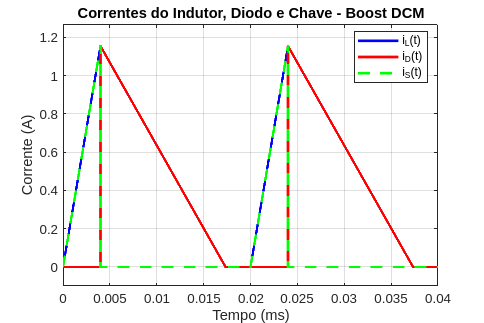


% Plotagem de 2 períodos
n_periodos = 2;
tempo_total = n_periodos * T;

% Resolução da simulação
pontos_por_periodo = NUM_POINTS;
tempo = linspace(0, tempo_total, n_periodos * pontos_por_periodo);

% Pré-alocar vetores
iL_sim = zeros(size(tempo));
iD_sim = zeros(size(tempo));
iS_sim = zeros(size(tempo));

% Gerar formas de onda para cada período
for k = 0:n_periodos-1
    % Índices para este período
    idx_inicio = k * pontos_por_periodo + 1;
    idx_fim = (k+1) * pontos_por_periodo;
    
    % Tempo dentro do período atual (0 a T)
    t_periodo = tempo(idx_inicio:idx_fim) - k*T;
    
    % Cálculo da corrente do indutor para este período (Boost DCM)
    iL_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Instante 0 até D*T: corrente vai de 0 até iL_max (chave ligada)
            iL_periodo(n) = iL_max * (t_periodo(n)/(D*T));
        elseif t_periodo(n) <= (D + D1)*T
            % Instante D*T até (D+D1)*T: corrente vai de iL_max até 0 (diodo conduzindo)
            t_rel = t_periodo(n) - D*T;
            iL_periodo(n) = iL_max * (1 - t_rel/(D1*T));
        else
            % Instante (D+D1)*T até T: corrente fica em 0 (descontinuidade)
            iL_periodo(n) = 0;
        end
    end
    
    % Cálculo da corrente do diodo para este período (Boost DCM)
    iD_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            % Instante 0 até D*T: corrente do diodo fica em 0 (chave fechada)
            iD_periodo(n) = 0;
        elseif t_periodo(n) <= (D + D1)*T
            % Instante D*T até (D+D1)*T: corrente do diodo = corrente do indutor
            % (diodo conduz a corrente do indutor para a carga)
            t_rel = t_periodo(n) - D*T;
            iD_periodo(n) = iL_max * (1 - t_rel/(D1*T));
        else
            % Instante (D+D1)*T até T: corrente do diodo fica em 0
            iD_periodo(n) = 0;
        end
    end

    % Corrente da chave
    iS_periodo = zeros(size(t_periodo));
    for n = 1:length(t_periodo)
        if t_periodo(n) <= D*T
            iS_periodo(n) = iL_periodo(n);
        else
            iS_periodo(n) = 0;
        end
    end
    
    % Armazenar
    iL_sim(idx_inicio:idx_fim) = iL_periodo;
    iD_sim(idx_inicio:idx_fim) = iD_periodo;
    iS_sim(idx_inicio:idx_fim) = iS_periodo;
end

% Gráfico
figure('Position', [100, 100, 900, 600]);
plot(tempo * 1000, iL_sim, 'b-', 'LineWidth', 2);
hold on;
plot(tempo * 1000, iD_sim, 'r-', 'LineWidth', 2);
plot(tempo * 1000, iS_sim, 'g--', 'LineWidth', 2);
grid on;
xlabel('Tempo (ms)');
ylabel('Corrente (A)');
title('Correntes do Indutor, Diodo e Chave - Boost DCM');
legend('i_L(t)', 'i_D(t)', 'i_S(t)', 'Location', 'best');
xlim([0, tempo_total * 1000]);
ylim([-0.1, iL_max * 1.1]);
hold off;


% Exibir valores calculados
fprintf('\n=== Valores Calculados para Boost DCM ===\n');


=== Valores Calculados para Boost DCM ===


fprintf('Tensão de entrada Vs = %.8f V\n', Vs);

Tensão de entrada Vs = 200.00000000 V


fprintf('Tensão de saída Vo = %.8f V\n', Vo);

Tensão de saída Vo = 260.00000000 V


fprintf('Tensão máxima na chave = %.8f V\n', Vo);

Tensão máxima na chave = 260.00000000 V


fprintf('Tensão máxima no diodo = %.8f V\n', Vo);

Tensão máxima no diodo = 260.00000000 V


fprintf('Duty cycle D = %.8f\n', D);

Duty cycle D = 0.20000000


fprintf('Resistência R = %.8f Ω\n', R);

Resistência R = 676.00000000 Ω


fprintf('Indutância L = %.8f mH\n', L*1000);

Indutância L = 0.69333333 mH


fprintf('iL_max = %.8f A\n', iL_max);

iL_max = 1.15384615 A


fprintf('D1 = %.8f\n', D1);

D1 = 0.66666667


fprintf('D2 = %.8f\n', D2);

D2 = 0.13333333


fprintf('Capacitância C = %.8f μF\n', C*1e6);

Capacitância C = 0.09861933 μF



% Informações adicionais sobre o conversor Boost DCM
fprintf('\n=== Características do Conversor Boost DCM ===\n');


=== Características do Conversor Boost DCM ===


fprintf('Tensão de saída maior que a tensão de entrada: Vo = %.2f V > Vs = %.2f V\n', Vo, Vs);

Tensão de saída maior que a tensão de entrada: Vo = 260.00 V > Vs = 200.00 V


fprintf('Relação de conversão: Vo/Vs = %.4f\n', Vo/Vs);

Relação de conversão: Vo/Vs = 1.3000
